downs = grabFromFilter('DOWN Cells');
ups = grabFromFilter('UP Cells');

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; 'SP10'; 'Extracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular', '_SP10'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

upPDs = []; %Store preferred directions
upDSIs = []; %store DSI
upCoordinates = zeros(0, 2);
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};
    
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end

    upPDs(end+1) = loc.Analysis_Results.PreferredDirection;
    upDSIs(end+1) = loc.Analysis_Results.DSI;
    if ~isfield(struct_i.coordinates, 'polar')
        upCoordinates = [upCoordinates; [NaN NaN]];
    else
        upCoordinates = [upCoordinates; struct_i.coordinates.polar];
    end
end

downPDs = [];
downDSIs = [];
downCoordinates = zeros(0, 2);
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};
    
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end

    downPDs(end + 1) = loc.Analysis_Results.PreferredDirection;
    downDSIs(end+1) = loc.Analysis_Results.DSI;
    downCoordinates = [downCoordinates; struct_i.coordinates.polar];
end



## DSI by cell type

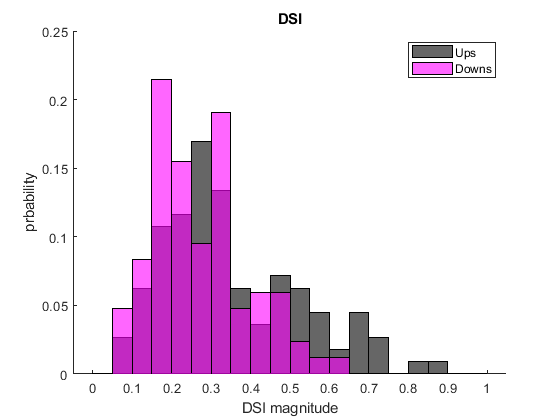

figure
title('DSI')
hold on
histogram(upDSIs, 'BinEdges', 0:0.05:1, 'FaceColor', 'black', 'Normalization','probability')
histogram(downDSIs,'BinEdges', 0:0.05:1, 'FaceColor', 'magenta', 'FaceAlpha', 0.6, 'Normalization','probability')
xlabel('DSI magnitude')
ylabel('prbability')
legend('Ups', 'Downs')

disp(['p = ', num2str(ranksum(upDSIs, downDSIs))])

p = 0.003253


## DSI vs Preferred Direction

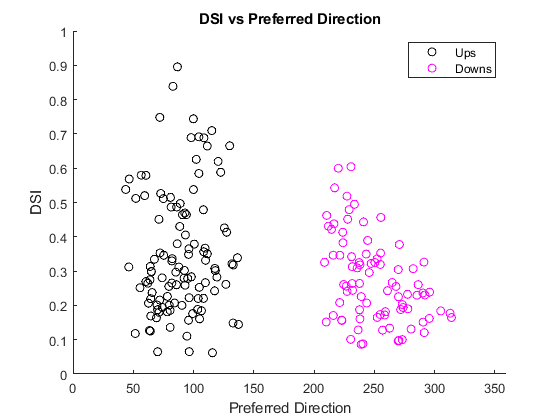

figure
title('DSI vs Preferred Direction')
hold on
scatter(mod(upPDs, 360), upDSIs, 'MarkerEdgeColor','black')
scatter(mod(downPDs, 360), downDSIs, 'MarkerEdgeColor', 'magenta')
xlabel('Preferred Direction')
ylabel('DSI')
xlim([0 360])
ylim([0 1])
legend('Ups', 'Downs')